# introduction to time-domain analyses

[mikeXcohen@gmail.com](mailto:mikeXcohen@gmail.com)

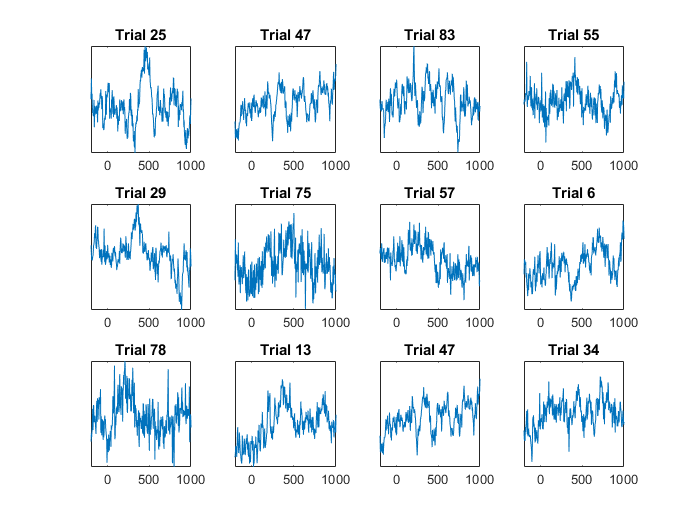

% load EEG data
load sampleEEGdata.mat

% plot a few trials from one channel...

% specify the label of the channel to plot
which_channel_to_plot = 'fcz';

% and find the index (channel number) of that label
channel_index = strcmpi(which_channel_to_plot,{EEG.chanlocs.labels});

x_axis_limit = [-200 1000]; % in ms

num_trials2plot = 12;


figure(1), clf
%set(gcf,'Name',[ num2str(num_trials2plot) ' random trials from channel ' which_channel_to_plot ],'Number','off')

for i=1:num_trials2plot
    
    % figure out how many subplots we need
    subplot(ceil(num_trials2plot/ceil(sqrt(num_trials2plot))),ceil(sqrt(num_trials2plot)),i)
    
    % pick a random trial (using randsample, which is in the stats toolbox)
    random_trial_to_plot = randsample(EEG.trials,1);
    % if you don't have the stats toolbox, use the following two lines:
    %random_trial_to_plot = randperm(EEG.trials);
    %random_trial_to_plot = random_trial_to_plot(1);
    
    % plot trial and specify x-axis and title
    plot(EEG.times,squeeze(EEG.data(channel_index,:,random_trial_to_plot)));
    set(gca,'xlim',x_axis_limit,'ytick',[])
    title([ 'Trial ' num2str(random_trial_to_plot) ])
end

## All trials and trial average (ERP)

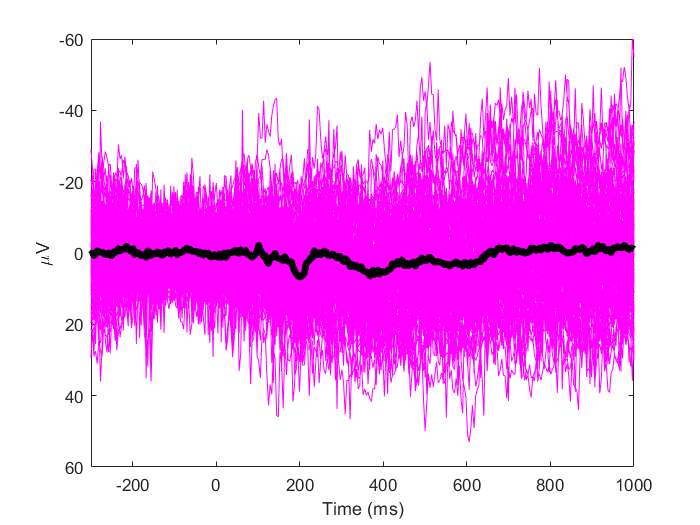

figure(2), clf
% plot all trials
plot(EEG.times,squeeze(EEG.data(channel_index,:,:)),'m')

hold on

% compute ERP
erp = mean(EEG.data(channel_index, :, :), 3);

% and plot it on top of single trials
plot(EEG.times,erp,'k','linew',4)
set(gca,'xlim',[-300 1000],'ylim',[-60 60],'ydir','reverse')
xlabel('Time (ms)'), ylabel('\muV')

## focus on the ERP

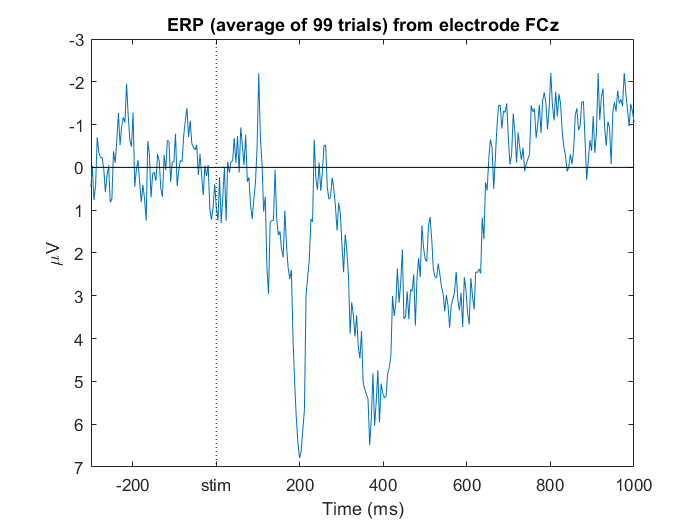

% now plot only the ERP
figure(3), clf
plot(EEG.times,erp) % Note the "3" as second input to "mean"; this takes the average of the 3rd dimension.

% plot lines indicating baseline activity and stim onset
hold on
plot(get(gca,'xlim'),[0 0],'k')
plot([0 0],get(gca,'ylim'),'k:')

% add axis labels and title
xlabel('Time (ms)')
ylabel('\muV') % note that matlab interprets "\mu" as the Greek character for micro
title([ 'ERP (average of ' num2str(EEG.trials) ' trials) from electrode ' EEG.chanlocs(channel_index).labels ])

% plot upside down, following ERP convention
set(gca,'ydir','reverse')
% axis ij % this does the same as the previous trial

% below is some advanced but flexible code to change the x-axis label
set(gca,'xlim',[-300 1000])
xticklabel=cellstr(get(gca,'xticklabel'));
xticklabel{str2double(xticklabel)==0}='stim';
set(gca,'xticklabel',xticklabel)

## Butterfly/topographical variance plots

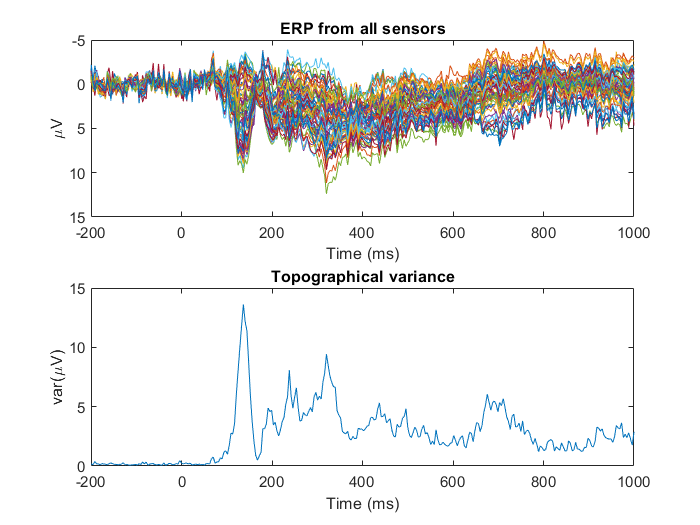

figure(4), clf

% Butterfly plot
subplot(211)
plot(EEG.times,mean(EEG.data,3))
set(gca,'xlim',[-200 1000],'ydir','reverse')
xlabel('Time (ms)'), ylabel('\muV')
title('ERP from all sensors')

% topographical variance plot
subplot(212)
plot(EEG.times,var( mean(EEG.data,3) )) % note: change var to std for global field power
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('var(\muV)')
title('Topographical variance')

## end.